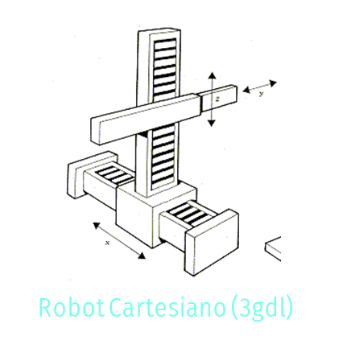

Mariam Landa Bautista A01736672

Declaración de configuración a través de la regla de la mano derecha, para obtener las matrices de transformación de cada articulación. 

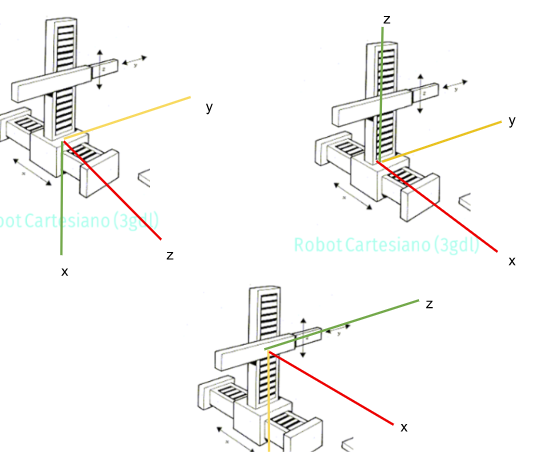

Este código se encarga de contruir las matrices de transformación, realizando la concatenación de las matrices de rotación, posición.

Tambien se obtiene la velocidad lineal y angular para cada articulación, utilizando el código del jacobiano y las velocidades, considerando los 3 eslabones.



%Limpieza de pantalla
clear all
close all
clc

% Declaración de las variables simbólicas
syms l1(t) l2(t) l3(t) t
syms l1p(t) l2p(t) l3p(t)    %Velocidades de cada articulación
syms m1 m2 m3 Ixx1 Iyy1 Izz1 Ixx2 Iyy2 Izz2 Ixx3 Iyy3 Izz3 %Masas y matrices de Inercia
syms lc1 lc2 lc3  %lc=distancia al centro de masa de cada eslabón
syms pi g a cero

% Configuración del robot, 0 para junta rotacional, 1 para junta prismática
RP = [1 1 1];
% Creamos el vector de coordenadas articulares
Q = [l1 l2 l3];
% Creamos el vector de velocidades articulares
Qp = [l1p l2p l3p]; 

% Número de grado de libertad del robot
GDL = size(RP, 2);
GDL_str = num2str(GDL);

% Definición de la posición de las articulaciones
% Articulación 1
% Posición de la junta 1 respecto al origen
P(:,:,1) = [0; 0; l1]; 

% Matriz de rotación de la articulación 1 respecto a 0
R(:,:,1) = [0 0 -1; 
            0 1 0;
            1 0 0];

% Articulación 2
%Posición de la articualción 2 respecto a 1
P(:,:,2) = [0; 0; l2];

%Matriz de rotación de la articulación 2 respecto a 1
R(:,:,2) = [1 0 0;
            0 0 1;
            0 -1 0];

% Articulación 3
%Posición de la articulación 3 respecto a 2
P(:,:,3) = [0; 0; l3]; 

%Matriz de rotación de la articulación 3 respecto a 2
R(:,:,3) = [1 0 0; 
            0 1 0; 
            0 0 1]; 

%Creamos un vector de ceros
Vector_Zeros= zeros(1, 3);

%Inicializamos las matrices de transformación Homogénea locales
A(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);
%Inicializamos las matrices de transformación Homogénea globales
T(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);
%Inicializamos las posiciones vistas desde el marco de referencia inercial
PO(:,:,GDL)= P(:,:,GDL); 
%Inicializamos las matrices de rotación vistas desde el marco de referencia inercial
RO(:,:,GDL)= R(:,:,GDL); 


for i = 1:GDL
    i_str= num2str(i);
   %disp(strcat('Matriz de Transformación local A', i_str));
    A(:,:,i)=simplify([R(:,:,i) P(:,:,i); Vector_Zeros 1]);
   %pretty (A(:,:,i));

   %Globales
    try
       T(:,:,i)= T(:,:,i-1)*A(:,:,i);
    catch
       T(:,:,i)= A(:,:,i);
    end
    %disp(strcat('Matriz de Transformación global T', i_str));
    T(:,:,i)= simplify(T(:,:,i));
    %pretty(T(:,:,i))

    RO(:,:,i)= T(1:3,1:3,i);
    PO(:,:,i)= T(1:3,4,i);
    %pretty(RO(:,:,i));
    %pretty(PO(:,:,i));
end

%Calculamos el jacobiano lineal de forma analítica
Jv_a(:,GDL)=PO(:,:,GDL);
Jw_a(:,GDL)=PO(:,:,GDL);

for k= 1:GDL
    if RP(k)==0 
       %Para las juntas de revolución
        try
            Jv_a(:,k)= cross(RO(:,3,k-1), PO(:,:,GDL)-PO(:,:,k-1));
            Jw_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)= cross([0,0,1], PO(:,:,GDL));%Matriz de rotación de 0 con respecto a 0 es la Matriz Identidad, la posición previa tambien será 0
            Jw_a(:,k)=[0,0,1];%Si no hay matriz de rotación previa se obtiene la Matriz identidad
         end
     else
         %Para las juntas prismáticas
        try
            Jv_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)=[0,0,1];
        end
            Jw_a(:,k)=[0,0,0];
     end
 end    

Jv_a= simplify (Jv_a);
Jw_a= simplify (Jw_a);
%disp('Jacobiano lineal obtenido de forma analítica');
%pretty (Jv_a);
%disp('Jacobiano ángular obtenido de forma analítica');
%pretty (Jw_a);

%disp('Velocidad lineal obtenida mediante el Jacobiano lineal');
V=simplify (Jv_a*Qp');
%pretty(V);
%disp('Velocidad angular obtenida mediante el Jacobiano angular');
W=simplify (Jw_a*Qp');
%pretty(W);


En esta parte se considera la distancia al centro de masa para cada eslabón, se declaran los vectores de posición respecto al centro de masa.

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%Energía Cinética
%%%%%%%%%%%%%%%%%%%%%%%%%%Omitimos la división de cada lc%%%%%%%%%%%%%%%
%Distancia del origen del eslabón a su centro de masa
%Vectores de posición respecto al centro de masa
 P01=subs(P(:,:,1), l1, lc1);%La función subs sustituye l1 por lc1 en 
 P12=subs(P(:,:,2), l2, lc2); %la expresión P(:,:,1)/2
 P23=subs(P(:,:,3), l3, lc3);

Se crean las matrices de inercia.

%Creamos matrices de inercia para cada eslabón

I1=[Ixx1 0 0; 
    0 Iyy1 0; 
    0 0 Izz1];

I2=[Ixx2 0 0; 
    0 Iyy2 0; 
    0 0 Izz2];

I3=[Ixx3 0 0; 
    0 Iyy3 0; 
    0 0 Izz3];

%Función de energía cinética

%Extraemos las velocidades lineales en cada eje
V=V(t);

Vx= V(1,1);
Vy= V(2,1);
Vz= V(3,1);

%Extraemos las velocidades angular en cada ángulo de Euler
W=W(t);
W_pitch= W(1,1);
W_roll= W(2,1);
W_yaw= W(3,1);

%Calculamos las velocidades para cada eslabón%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%Eslabón 1

%Calculamos el jacobiano lineal y angular de forma analítica
Jv_a1(:,GDL-2)=PO(:,:,GDL-2);
Jw_a1(:,GDL-2)=PO(:,:,GDL-2);

for k= 1:GDL-2
    if RP(k)==0 
       %Para las juntas de revolución
        try
            Jv_a1(:,k)= cross(RO(:,3,k-1), PO(:,:,GDL-2)-PO(:,:,k-1));
            Jw_a1(:,k)= RO(:,3,k-1);
        catch
            Jv_a1(:,k)= cross([0,0,1], PO(:,:,GDL-2));%Matriz de rotación de 0 con respecto a 0 es la Matriz Identidad, la posición previa tambien será 0
            Jw_a1(:,k)=[0,0,1];%Si no hay matriz de rotación previa se obtiene la Matriz identidad
         end
     else
%         %Para las juntas prismáticas
        try
            Jv_a1(:,k)= RO(:,3,k-1);
        catch
            Jv_a1(:,k)=[0,0,1];
        end
            Jw_a1(:,k)=[0,0,0];
     end
 end    

%Obtenemos SubMatrices de Jacobianos
Jv_a1= simplify (Jv_a1);
Jw_a1= simplify (Jw_a1);
%disp('Jacobiano lineal obtenido de forma analítica');
%pretty (Jv_a);
%disp('Jacobiano ángular obtenido de forma analítica');
%pretty (Jw_a);

%Matriz de Jacobiano Completa
%disp('Matriz de Jacobiano');
Jac1= [Jv_a1;
      Jw_a1];
Jacobiano1= simplify(Jac1);
% pretty(Jacobiano);

%Obtenemos vectores de Velocidades Lineales y Angulares
 %disp('Velocidad lineal obtenida mediante el Jacobiano lineal del Eslabón 1');
Qp=Qp(t);
V1=simplify (Jv_a1*Qp(1));
 %pretty(V1);
 % disp('Velocidad angular obtenida mediante el Jacobiano angular del Eslabón 1');
W1=simplify (Jw_a1*Qp(1));
 % pretty(W1);


%Eslabón 2

%Calculamos el jacobiano lineal de forma analítica
Jv_a2(:,GDL-1)=PO(:,:,GDL-1);
Jw_a2(:,GDL-1)=PO(:,:,GDL-1);

for k= 1:GDL-1
    if RP(k)==0 
       %Para las juntas de revolución
        try
            Jv_a2(:,k)= cross(RO(:,3,k-1), PO(:,:,GDL-1)-PO(:,:,k-1));
            Jw_a2(:,k)= RO(:,3,k-1);
        catch
            Jv_a2(:,k)= cross([0,0,1], PO(:,:,GDL-1));%Matriz de rotación de 0 con respecto a 0 es la Matriz Identidad, la posición previa tambien será 0
            Jw_a2(:,k)=[0,0,1];%Si no hay matriz de rotación previa se obtiene la Matriz identidad
         end
     else
%         %Para las juntas prismáticas
        try
            Jv_a2(:,k)= RO(:,3,k-1);
        catch
            Jv_a2(:,k)=[0,0,1];
        end
            Jw_a2(:,k)=[0,0,0];
     end
 end    

%Obtenemos SubMatrices de Jacobianos
Jv_a2= simplify (Jv_a2);
Jw_a2= simplify (Jw_a2);
%disp('Jacobiano lineal obtenido de forma analítica');
%pretty (Jv_a);
%disp('Jacobiano ángular obtenido de forma analítica');
%pretty (Jw_a);

%Matriz de Jacobiano Completa
%disp('Matriz de Jacobiano');
Jac2= [Jv_a2;
      Jw_a2];
Jacobiano2= simplify(Jac2);
% pretty(Jacobiano);

%Obtenemos vectores de Velocidades Lineales y Angulares
%disp('Velocidad lineal obtenida mediante el Jacobiano lineal del Eslabón 2');
V2=simplify (Jv_a2*Qp(1:2)');
% pretty(V2);
%disp('Velocidad angular obtenida mediante el Jacobiano angular del Eslabón 2');
W2=simplify (Jw_a2*Qp(1:2)');
% pretty(W2);

%Calculamos la energía cinética para cada uno de los eslabones%%%%%%%%%%

Se declaran las ecuaciones de energía cinética para cada eslabón, donde se cosidera el cuadro de velocidades, masa e inercias. Se realiza la sumatoria de la energía cinética para cada eslabón.

%Eslabón 1
V1_Total= V1+cross(W1,P01);
K1= (1/2*m1*(V1_Total))'*((V1_Total)) + (1/2*W1)'*(I1*W1);
disp('Energía Cinética en el Eslabón 1');

Energía Cinética en el Eslabón 1


K1= simplify (K1);
pretty (K1);

        2 __
|l1p(t)|  m1
------------
      2





%Eslabón 2
V2_Total= V2+cross(W2,P12);
K2= (1/2*m2*(V2_Total))'*((V2_Total)) + (1/2*W2)'*(I2*W2);
disp('Energía Cinética en el Eslabón 2');

Energía Cinética en el Eslabón 2


K2= simplify (K2);
pretty (K2);

__          2           2
m2 (|l1p(t)|  + |l2p(t)| )
--------------------------
             2





%Eslabón 3
V3_Total= V+cross(W,P23);
K3= (1/2*m3*(V3_Total))'*((V3_Total)) + (1/2*W)'*(I3*W);
disp('Energía Cinética en el Eslabón 3');

Energía Cinética en el Eslabón 3


K3= simplify (K3);
pretty (K3);

__          2           2           2
m3 (|l1p(t)|  + |l2p(t)|  + |l3p(t)| )
--------------------------------------
                   2




K_Total= simplify (K1+K2+K3);
pretty(K_Total)

__          2           2           2            2 __   __          2           2
m3 (|l1p(t)|  + |l2p(t)|  + |l3p(t)| )   |l1p(t)|  m1   m2 (|l1p(t)|  + |l2p(t)| )
-------------------------------------- + ------------ + --------------------------
                   2                           2                     2

